close all
clear all

num = xlsread("proyecto.xlsx")

num = 	1.0e+03 *

   -0.0000    0.0623   -0.0000    0.0290    0.0000    0.7572
         0    0.0623    0.0000    0.0292    0.0000    0.7805
    0.0000    0.0628    0.0000    0.0295    0.0000    0.7960
   -0.0000    0.0626    0.0000    0.0297    0.0000    0.7969
   -0.0000    0.0626    0.0000    0.0298   -0.0000    0.7959
    0.0000    0.0632    0.0000    0.0299    0.0000    0.7990
   -0.0000    0.0626   -0.0000    0.0298    0.0000    0.8136
    0.0000    0.0627   -0.0000    0.0298    0.0000    0.8171
   -0.0000    0.0625    0.0000    0.0300   -0.0000    0.8097
   -0.0000    0.0625   -0.0000    0.0300   -0.0000    0.8075


precio1 = num(:,1)

precio1 =    -0.0045
         0
    0.0087
   -0.0032
   -0.0003
    0.0091
   -0.0092
    0.0014
   -0.0027
   -0.0005


precio2 = num(:,3)

precio2 =    -0.0011
    0.0051
    0.0111
    0.0092
    0.0010
    0.0054
   -0.0042
   -0.0018
    0.0081
   -0.0001


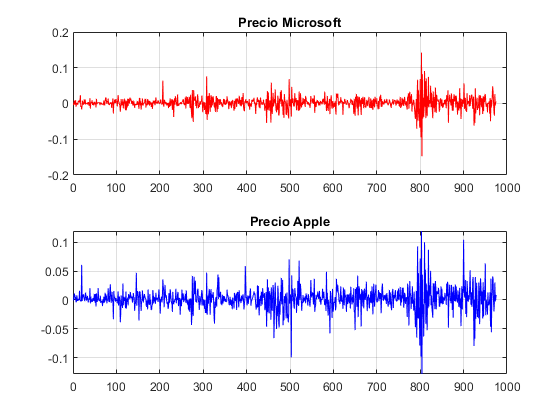

figure
subplot(2,1,1)
plot(precio1,'r');
title('Precio Microsoft')
grid on
subplot(2,1,2);
plot(precio2,'b');
title('Precio Apple')
grid on

numseries = 2

numseries = 2

est = [precio1 precio2]

est =    -0.0045   -0.0011
         0    0.0051
    0.0087    0.0111
   -0.0032    0.0092
   -0.0003    0.0010
    0.0091    0.0054
   -0.0092   -0.0042
    0.0014   -0.0018
   -0.0027    0.0081
   -0.0005   -0.0001


VAR2 = varm(2,4)

VAR2 =   varm with properties:

     Description: "2-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2" 
       NumSeries: 2
               P: 4
        Constant: [2×1 vector of NaNs]
              AR: {2×2 matrices of NaNs} at lags [1 2 3 ... and 1 more]
           Trend: [2×1 vector of zeros]
            Beta: [2×0 matrix]
      Covariance: [2×2 matrix of NaNs]

sum1 = estimate(VAR2,est)

sum1 =   varm with properties:

     Description: "AR-Stationary 2-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2" 
       NumSeries: 2
               P: 4
        Constant: [0.00197147 0.0019672]'
              AR: {2×2 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [2×1 vector of zeros]
            Beta: [2×0 matrix]
      Covariance: [2×2 matrix]

summarize(sum1)

 
   AR-Stationary 2-Dimensional VAR(4) Model
 
    Effective Sample Size: 971
    Number of Estimated Parameters: 18
    LogLikelihood: 5376.62
    AIC: -10717.2
    BIC: -10629.4
 
                     Value       StandardError    TStatistic      PValue  
                   __________    _____________    __________    __________

    Constant(1)     0.0019715     0.00057305         3.4403     0.00058103
    Constant(2)     0.0019672     0.00064208         3.0638      0.0021855
    AR{1}(1,1)       -0.30875       0.047442        -6.5079     7.6202e-11
    AR{1}(2,1)       -0.23075       0.053157        -4.3409     1.4191e-05
    AR{1}(1,2)     -0.0058208       0.042362       -0.13741        0.89071
    AR{1}(2,2)      0.0068041       

num_periodos = 300

num_periodos = 300

[Predic1,Predic2]=forecast(sum1,num_periodos,est)

Predic1 =    -0.0008    0.0007
    0.0030    0.0030
    0.0006    0.0008
    0.0013    0.0017
    0.0016    0.0018
    0.0013    0.0016
    0.0015    0.0016
    0.0014    0.0016
    0.0014    0.0016
    0.0015    0.0017


Predic2 = 300×1 cell array
    {2×2 double}
    {2×2 double}
    {2×2 double}
    {2×2 double}
    {2×2 double}
    {2×2 double}
    {2×2 double}
    {2×2 double}
    {2×2 double}
    {2×2 double}
    {2×2 double}
    {2×2 double}
    {2×2 double}
    {2×2 double}
    {2×2 double}
    {2×2 double}


tn = length(precio1): (length(precio1)+num_periodos-1)

tn =          975         976         977         978         979         980         981         982         983         984         985         986         987         988         989         990         991         992         993         994         995         996         997         998         999        1000        1001        1002        1003        1004        1005        1006        1007        1008        1009        1010        1011        1012        1013        1014        1015        1016        1017        1018        1019        1020        1021        1022        1023        1024


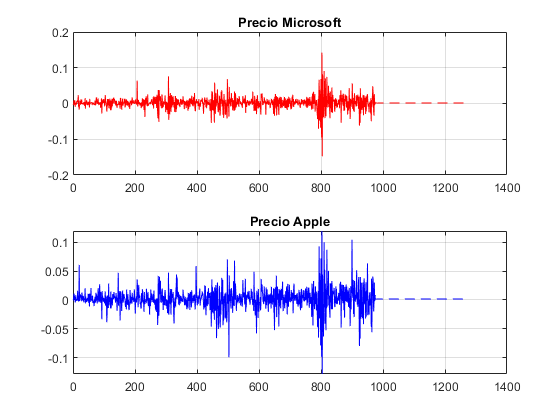


figure
subplot(2,1,1)
plot(precio1,'r');
hold on
plot(tn,Predic1(:,1),'r--')
title('Precio Microsoft')
grid on
subplot(2,1,2);
plot(precio2,'b');
hold on
plot(tn,Predic1(:,2),'b--')
title('Precio Apple')
grid on